Image = imread('rgb_image1.jpg')

Image = 400×500×3 uint8 array
Image(:,:,1) =

   173   172   173   174   176   177   178   178   179   179   179   179   179   179   179   179   179   178   176   176   175   175   175   175   172   170   173   173   169   168   168   165   163   163   161   156   149   141   133   128   127   124   121   120   120   120   120   120   122   125   141   157   159   156   154   151   151   151   151   150   151   153   156   158   159   143   126   104    88    80    76    79    78    78    78    79    79    80    84    88    92    94   102   104   106   110   109   112   112   114   117   120   121   121   121   123   128   135   139   143   145   142   138   139   137   140   141   141   141   143   143   142   139   141   142   142   141   142   146   151   151   152   154   157   159   159   159   158   163   163   163   161   158   157   157   157   164   162   162   164   165   165   165   166   170   170   170   171   171   170   171   172   171   171   172   172   172   172   172

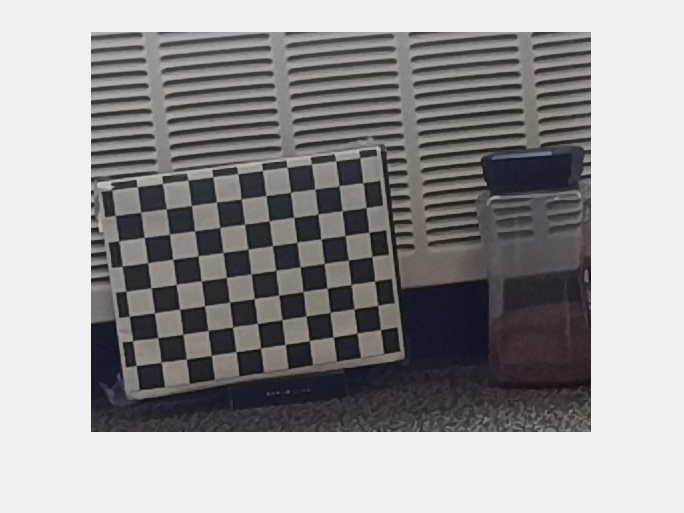

x =   317.0000
    3.0000


y =    328
   157


imshow(Image);
[x,y] = ginput(2)


% image coordinates
cam_x2 = max(x)

cam_x2 = 317.0000

cam_x1 = min(x)

cam_x1 = 3.0000

cam_y2 = max(y)

cam_y2 = 328

cam_y1 = min(y)

cam_y1 = 157


% focal points obtained from cameraparameters here
focal_x = 1956.510454784993

focal_x = 1.9565e+03

focal_y = 1951.901777401675

focal_y = 1.9519e+03

principal_x = 256.3547744228429

principal_x = 256.3548

principal_y = 303.6839320986269

principal_y = 303.6839


% distance between camera and object
distance = 1574.8

distance = 1.5748e+03


% world coordinates
world_x1 = distance*(cam_x1)/focal_x

world_x1 = 2.4147

world_y1 = distance*(cam_y1)/focal_y

world_y1 = 126.6681

world_x2 = distance*(cam_x2)/focal_x

world_x2 = 255.1541

world_y2 = distance*(cam_y2)/focal_y

world_y2 = 264.6313

z0 = distance

z0 = 1.5748e+03


% the image obtained
real = Image(min(y):max(y),min(x):max(x));

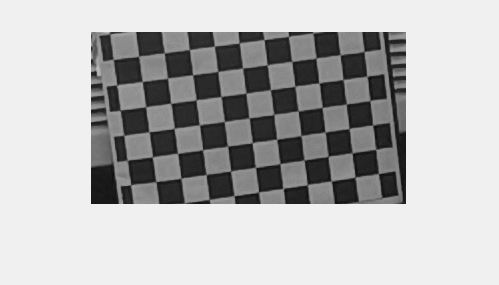

imshow(real);


% distance between two choosen points
distance = sqrt((world_x2-world_x1)^2+(world_y2-world_y1)^2)

distance = 287.9428

distance;
